% 此示例说明如何使用神经网络作为分类器来根据螃蟹的物理尺寸识别螃蟹的性别。
% 问题：螃蟹的分类
% 在此示例中，我们尝试构建一个可根据螃蟹的物理测量值识别螃蟹性别的分类器。
% 我们将考虑螃蟹的六个物理特征：品种、前鳌、背宽、长度、宽度和厚度。
% 现有问题是根据这 6 个物理特征的观测值识别螃蟹的性别。
% 
% 为什么使用神经网络？
% 神经网络已证明是成熟的分类器，特别适合处理非线性问题。
% 鉴于真实情况（如螃蟹分类）的非线性特性，神经网络无疑是解决该问题的优选方案。
% 六个物理特征将作为神经网络的输入，螃蟹的性别将成为目标。
% 根据由螃蟹的六个物理特征观测值构成的输入，神经网络应识别出螃蟹是雄性还是雌性。
% 这通过将先前记录的输入提交给神经网络，然后调整网络以产生期望的目标输出来实现。此过程称为神经网络训练。

## 准备数据

通过将数据组织成两个矩阵（输入矩阵 X 和目标矩阵 T）来为神经网络设置分类问题的数据。 输入矩阵的每个第 i 列将具有六个元素，表示螃蟹的品种、前鳌、背宽、长度、宽度和厚度。 目标矩阵的每个对应列将具有两个元素。第一个元素中的一表示雌蟹，第二个元素中的一表示雄蟹。 （所有其他元素均为零。）% 使用以下命令加载该数据集。

[x,t] = crab_dataset;
size(x) %  6 *  200

ans =      6   200


size(t) %  2 *  200

ans =      2   200


## 构建神经网络分类器

下一步是创建一个学习识别螃蟹性别的神经网络。 由于神经网络以随机初始权重开始，因此该示例的结果在每次运行时都会略有不同。 我们设置了随机种子来避免这种随机性。但这对于您自己的应用情形并不是必需的。

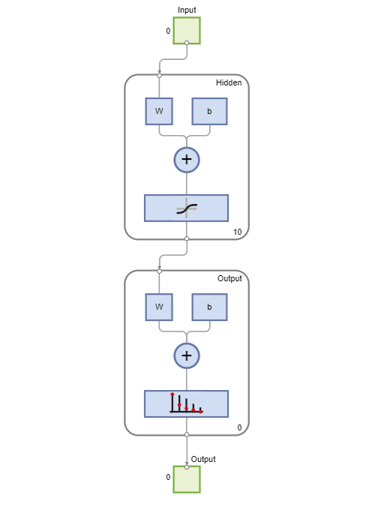

setdemorandstream(491218382)
% 双层（即，一个隐藏层）前馈神经网络可以学习任何输入-输出关系，
% 前提是隐藏层中有足够的神经元。非输出层称为隐含层。
% 对于此示例，我们将尝试具有 10 个神经元的单隐藏层。
% 一般情况下，问题越困难，需要的神经元和层就越多。问题越简单，需要的神经元就越少。
% 输入和输出的大小为 0，因为网络尚未配置成与我们的输入数据和目标数据相匹配。
% 这将在训练网络时进行。

net = patternnet(10);
view(net)

## 训练网络

现在网络已准备就绪，可以开始训练。样本自动分为训练集、验证集和测试集。 训练集用于对网络进行训练。只要网络针对验证集持续改进，训练就会继续。 测试集提供完全独立的网络准确度测量。

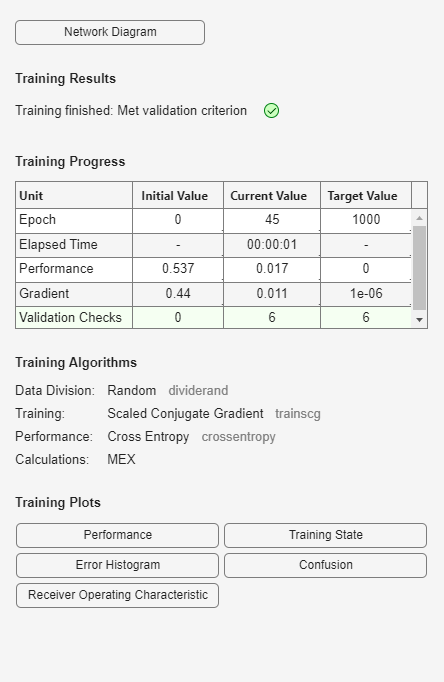

[net,tr] = train(net,x,t);

nntraintool

Unrecognized function or variable 'nntraintool'.



nntraintool('close')
% 要查看在训练过程中网络性能的改善情况，请点击训练工具中的 Performance 按钮，或调用 PLOTPERFORM。
% 性能以均方误差衡量，并以对数刻度显示。随着网络训练的加深，均方误差迅速降低。
% 绘图会显示训练集、验证集和测试集的性能。

plotperform(tr)

## 测试分类器

现在可以使用测试样本测试经过训练的神经网络。这将使我们能够了解网络在应用于真实数据时表现如何。

网络输出的范围为 0 到 1，因此我们可以使用 vec2ind 函数根据每个输出向量中最高元素的位置来获取类索引。

testX = x(:,tr.testInd);
testT = t(:,tr.testInd);

testY = net(testX);
testIndices = vec2ind(testY)
% 
% 衡量神经网络数据拟合程度的一个方法是混淆矩阵图。下面绘制了所有样本的混淆矩阵图。
% 该混淆矩阵显示了正确和错误分类的百分比。
% 正确分类表示为矩阵对角线上的绿色方块。错误分类表示为红色方块。
% 如果网络已学会正确分类，则红色方块中的百分比应该非常小，表示几乎没有错误分类。
% 如果不是这样，则建议进一步进行训练，或训练具有更多隐藏神经元的网络。

plotconfusion(testT,testY)

## 以下是正确和错误分类的总体百分比。

[c,cm] = confusion(testT,testY)

fprintf('Percentage Correct Classification   : %f%%\n', 100*(1-c));
fprintf('Percentage Incorrect Classification : %f%%\n', 100*c);
% c =    0.0333
% cm =    12     1
%      0    17

% Percentage Correct Classification   : 96.666667%
% Percentage Incorrect Classification : 3.333333%
% 衡量神经网络数据拟合程度的另一个方法是受试者工作特征图。
% 该图可显示随着输出阈值从 0 变为 1，假正率和真正率之间的相关性。

% 线条越偏向左上方，达到高的真正率所需接受的假正数越少。
% 最佳分类器是线条从左下角到左上角再到右上角，或接近于该模式。

plotroc(testT,testY)